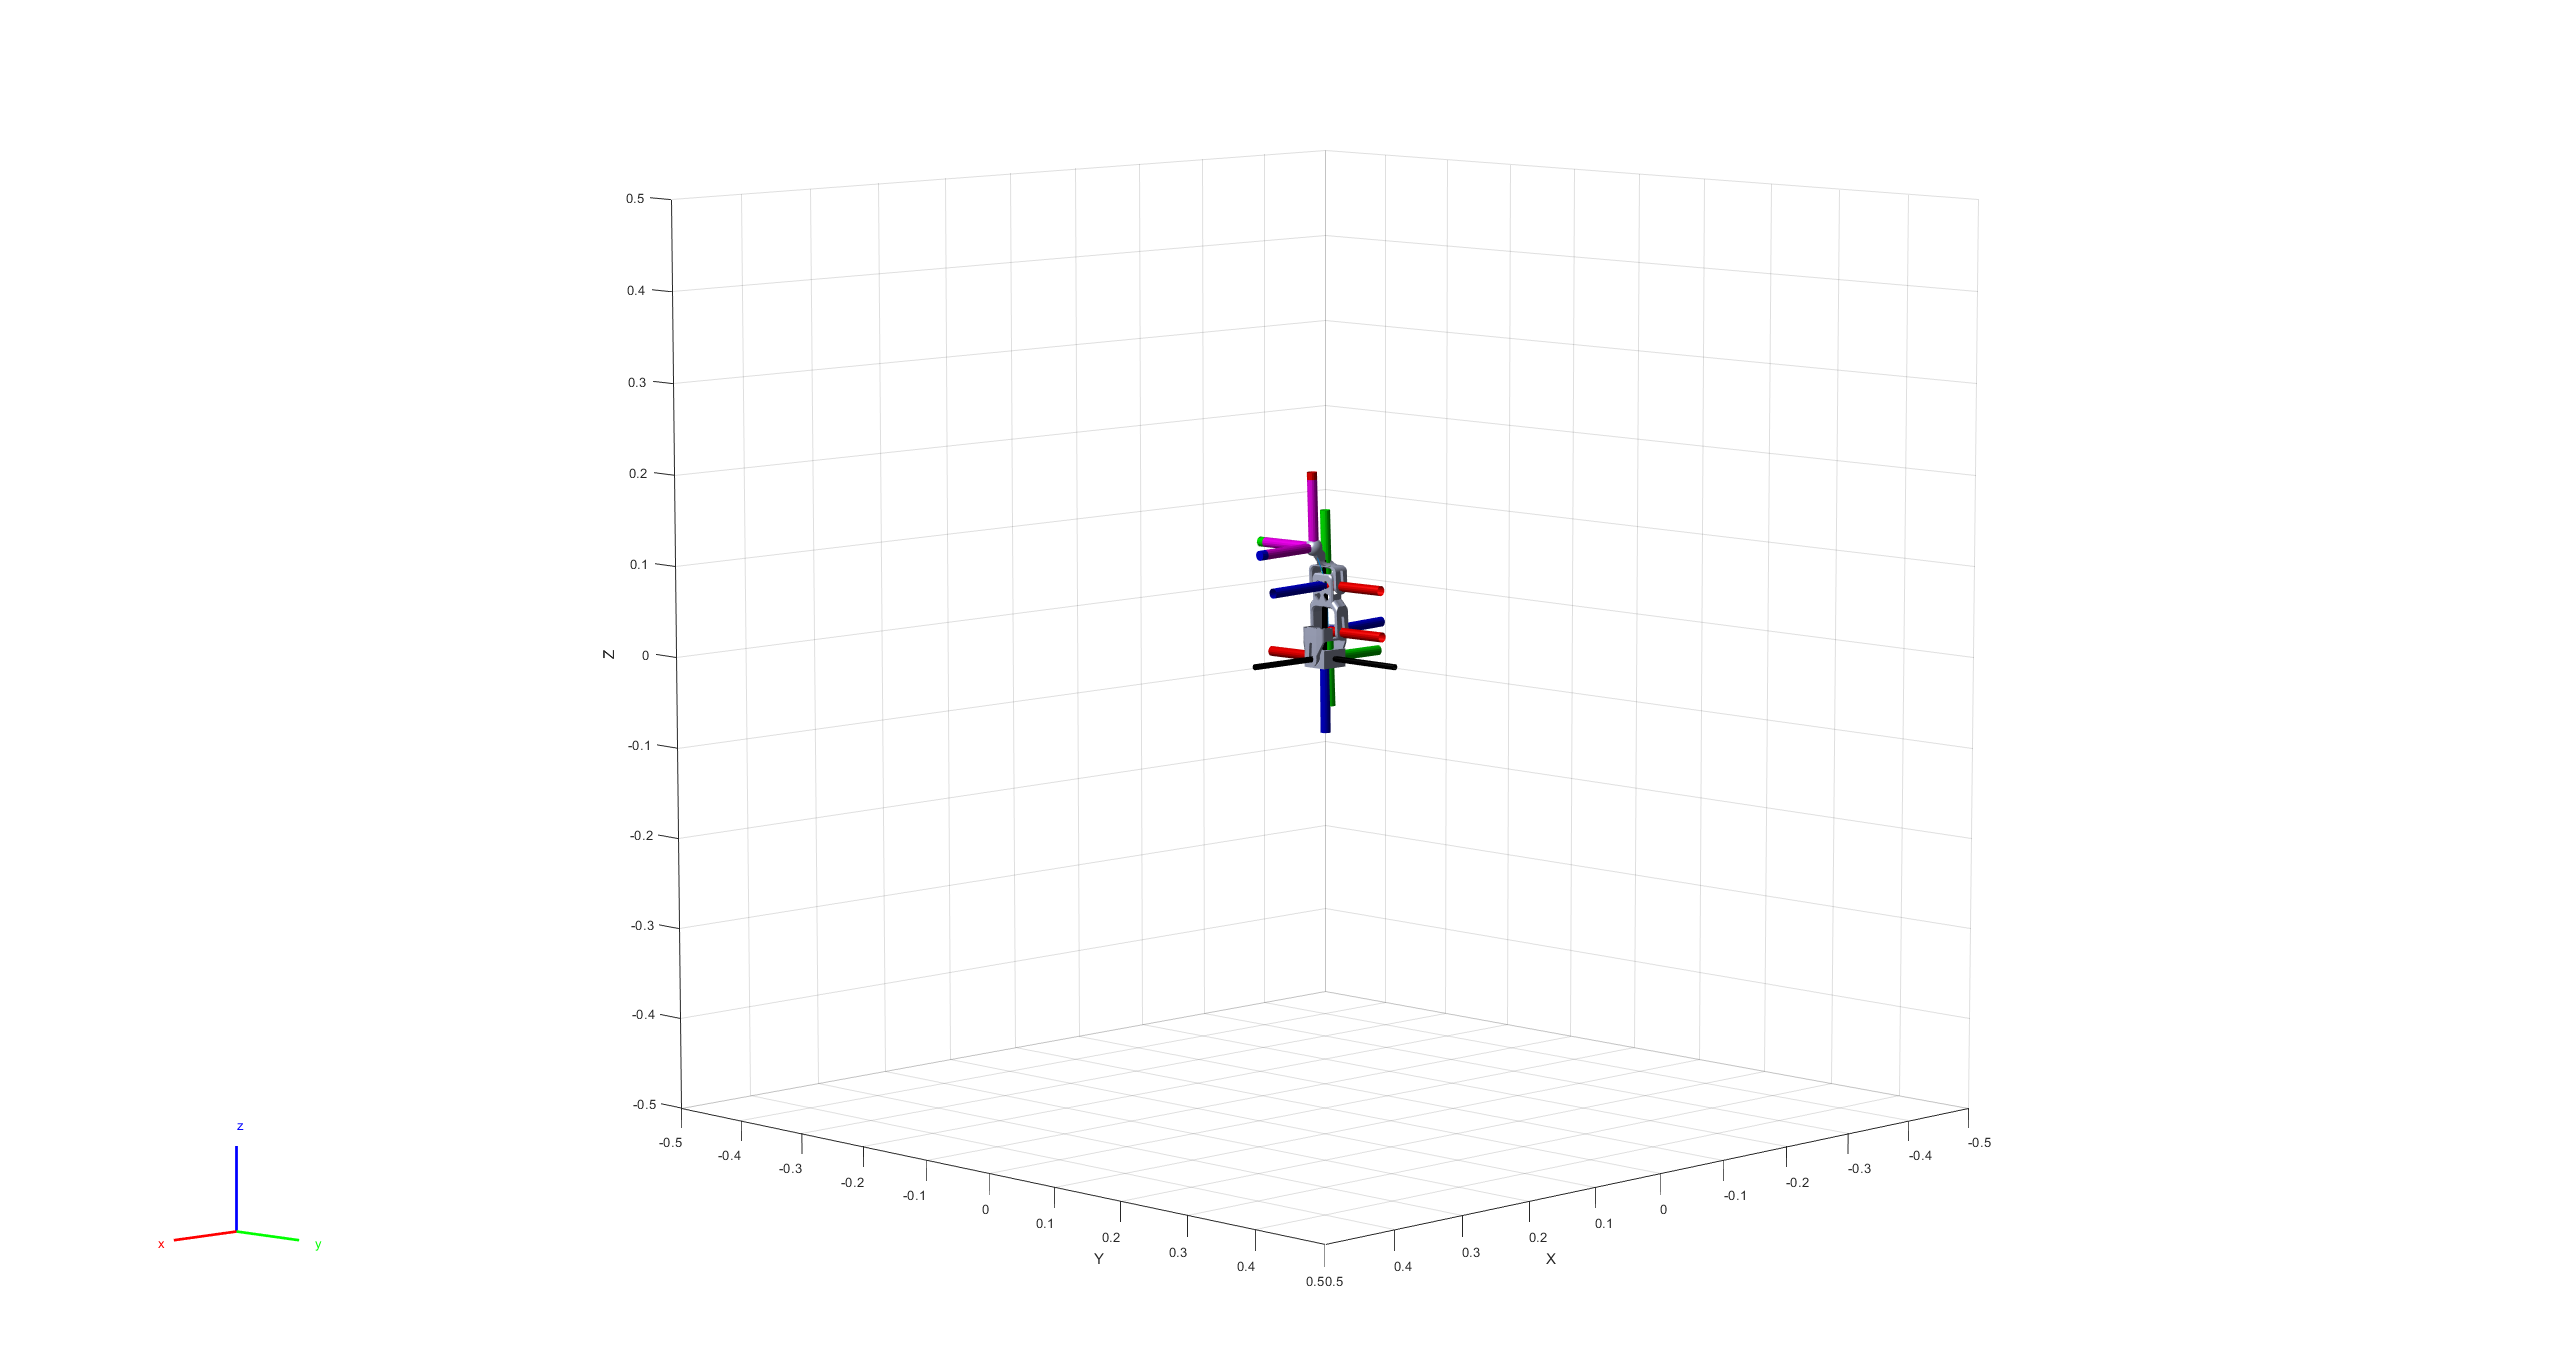

clear
clc

%-- Base Variables --%
t = linspace(0,1,100);
L = .05;

%-- Trajectory --%
x = (-2*L*(t.^3))+(3*L*(t.^2))-(L/2);
y = (.015/2)*sin((x+L/4)*(2*pi/L))+(.015/2);

%-- Small Kat Leg Import --%
robot = importrobot("Exra_LegV2\urdf\Exra_LegV2.urdf");
show(robot);

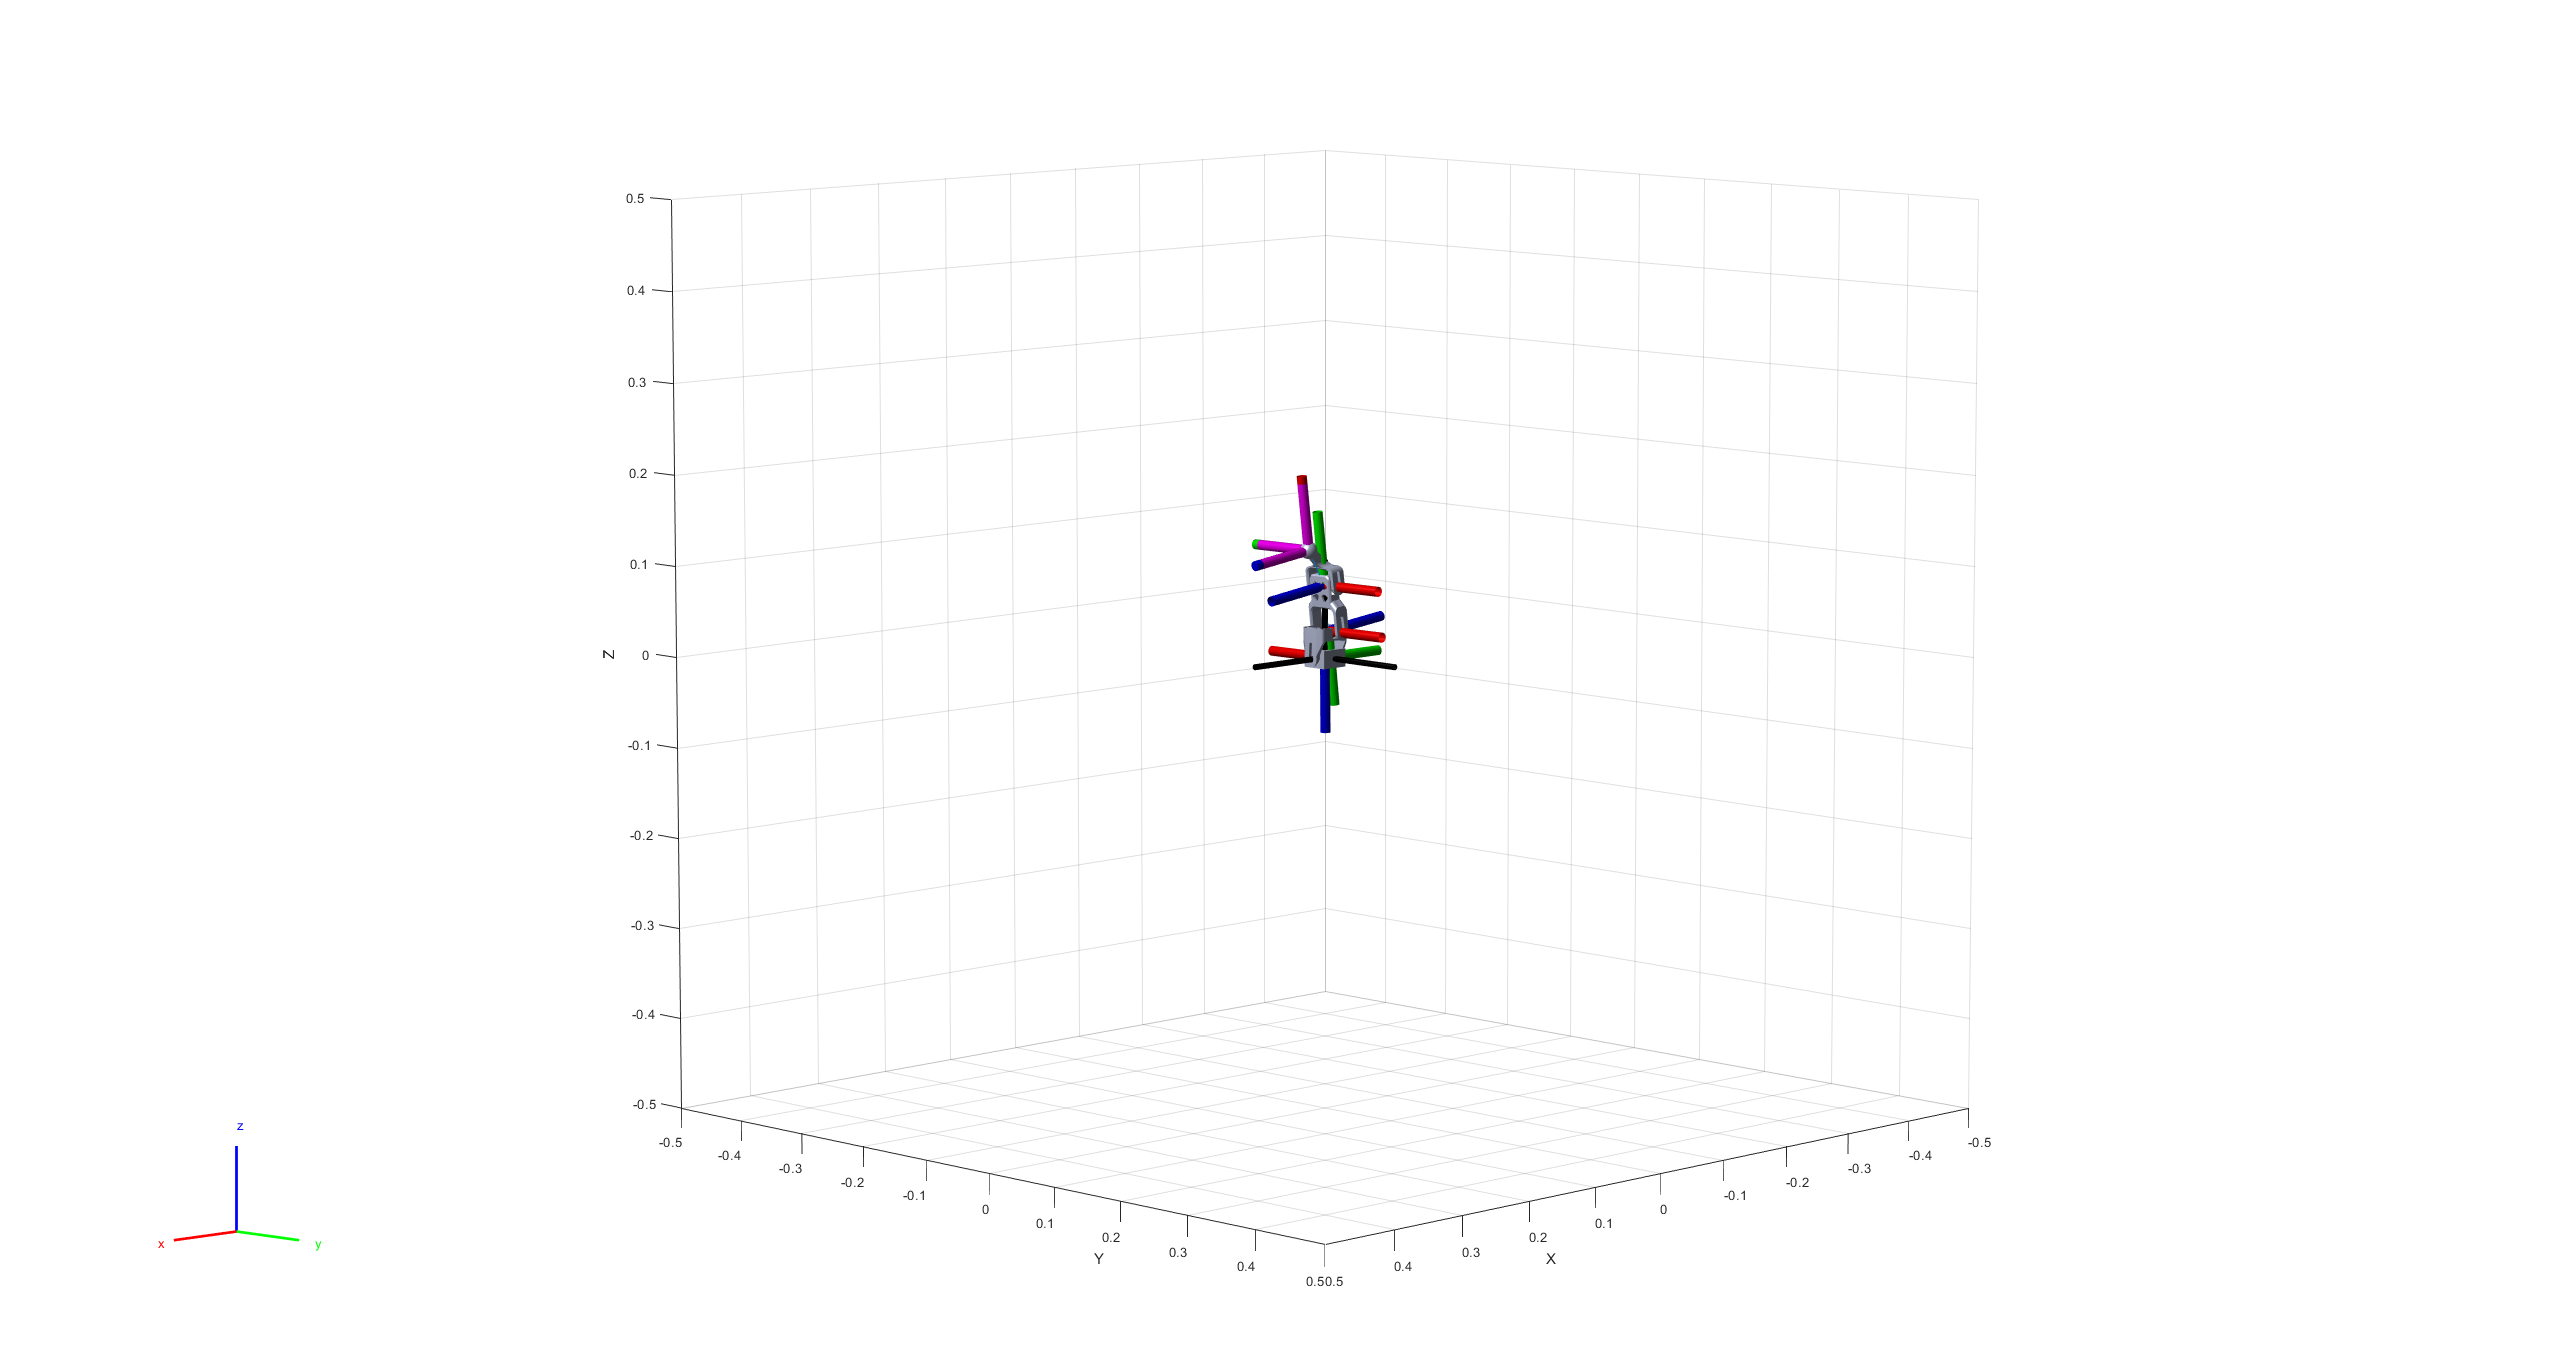

% showdetails(robot);

%-- Inverse Kinematics to solve Trajectories --%
ik = inverseKinematics('RigidBodyTree',robot);
weights = [0 0 0 1 1 1];
initialguess = robot.homeConfiguration;

configs = pathCalc(ik,weights,initialguess,x,y,robot);

%-- Display Motion --%
for i = 1:size(configs,2)

    configures = homeConfiguration(robot);

    configures(1).JointPosition = configs(1,i);
    configures(2).JointPosition = configs(2,i);
    configures(3).JointPosition = configs(3,i);

    show(robot,configures);

    pause(.005)

end


%-- Plot Path --%
plot3(x,zeros(1,length(x)),y);

function configs = pathCalc(ik,weights,initialguess,x,y,robot)

configs = zeros(3,length(x));

    for i = 1:length(x)
    
        tform = trvec2tform([x(i) 0 -y(i)+.12]);
    
        [configSoln,~] = ik('Toe_Link',tform,weights,initialguess);

        configs(:,i) = [configSoln(1).JointPosition; configSoln(2).JointPosition; configSoln(3).JointPosition];
    
    end

end